# Exercise 2: Coding by receptor afferents and responses of central neurons 

**Goal: **In this exercise, we’ll be looking at how peripheral electroreceptors respond to stimuli such as SAMs, RAMs, and envelopes (see Background.mlx for more information).

## Experiment

The fish will be paralyzed by intramuscular curare injection. This blocks the neuromuscular junction, but since the electric organ is a modified axon in *Apteronotus*, its electric field is unaffected by the drug.

Importantly, the fish will not be able to use its gills to respire, and therefore artificial respiration is necessary – which is achieved by directing a flow of water into the fish’s mouth. Maintaining this flow is critical for the survival of the animal and for the success of the experiment. As much as we don’t like water in our lungs, these guys **DON’T** like air in their gills. If you see an air bubble, inform one of us immediately.

On the oscilloscope, you’ll see a sinusoidal-like waveform. This is the animal’s electric organ discharge (EOD). Turn on the audio monitor to hear it - it should sound like a pure tone. 

These animals expend most of their metabolic energy producing this field: it is thus a very good indicator of the overall health of the animal. 

***IT IS VERY IMPORTANT FOR YOU TO MONITOR THE EOD AMPLITUDE: IMMEDIATELY INFORM ONE OF US IF YOU SEE ANY SUDDEN LARGE DECREASE IN EOD AMPLITUDE.***  

NOTE: Fish are cold-blooded vertebrates; this means that their metabolic activity decreases with temperature and this includes the generation of their EOD. 

The main water flows from one bucket (which has a heater, and a bubbler for oxygenation) to the main tank that flows back to the bucket. It’s important not to have the flow rate too high otherwise the pump will not be able to keep up and the tank will overflow. 

## Recordings

- When you’re ready, pull some micropipettes using the Sutter puller and fill them with 3M KCl.

- Place the micropipette in the holder at the tip of the micropositioner. The electrode should be approximately vertical.

- Use the positioner to lower the electrode so that the tip is in the saline.

-  Use the motor control to lower the electrode until you hit the surface of the brain

- Zero the depth monitor and begin to slowly lower the electrode in steps of 2 μm: don’t forget to buzz every once in a while. You should start seeing receptor afferents at about 900 μm (depending on where the electrode penetrated). Be patient, if you go too fast, the recordings will not be as stable.

Receptor afferents have large firing rates (150-500 spikes/sec) and are spontaneously active: make sure the signal-to-noise ratio (SNR) is large enough to trigger spikes reliably. Ask one of us if you’re not sure. Try recording baseline activity from a few units (50 seconds will be plenty). You should find plenty of receptors but holding the recording for more than 1-2 minutes is tough. Try buzzing again if the SNR gets too low, or try going up or down one step and buzzing again. 

# Exercise 3: Responses of central neurons

## Recordings:

Depending on penetration site, the summed activity of PCells should be registered on the recording electrode from about 500 μm on. PCells have low firing rates (5-50 spikes/sec), will typically show phase-locking to the search stimulus, and are also spontaneously active [make sure the signal-to-noise ratio is large enough to trigger spikes reliably for analysis]. To record from PCells:

- Place 2 W*ood's *metal electrodes in the micromanipulators 

- Use the motor control to slower lower the electrodes until you reach the surface of the brain

- Zero the depth monitor

-  Gently lower the electrodes into the brain wile stimulating the animal with a globas 4 Hz AM "search stimulus". Be patient, if the electrode is advanced too quickly, the tissue will be damaged and any recordings established will be less stable.

- Try recording baseline activity from a few PCell untis - about 1 minute each. If you used the search stimulus, be sure to let the activity recover (~ 1 min no stimulation) before recording baseline activity. 

NOTE: Remember to rinse the craniotomy with saline frequently between recordings!

## Stimulation

Once you have established a stable recording, use the global electrodes on each side of the animal to deliver amplitude modulations of the animal’s own EOD. The EOD acts like a carrier and stimuli will consist of amplitude (and phase) modulations of this EOD (just like in a radio). The relevant signal during analysis will be this amplitude modulation rather than the full signal. The fish has separate neural pathways processing amplitude and phase modulations of the EOD: here we will be studying the pathway that codes for amplitude modulations exclusively. 

Stimulation can be applied through the buttons in the stimulation panel in Spike2. 

- Try recording PCell responses to sinusoidal AMs at 1, 2, 4, 8, 16, 32, 64, 128, 256 Hz. Each stimulus should be applied for at least 15-20 seconds. 

- Stimulation with random amplitude modulations (RAM). For this we prepared noise in the range of 0-120 Hz. 

- See how PCells respond to contrast modulated SAMs (this simulates what a fish might experience during an agonistic or courtship encounter). These are “envelopes” of the AM of the EOD (*i.e., an amplitude modulation of the amplitude modulation*) with different carrier frequencies (AM bandwidths)

- Don’t forget to adjust the stimulus intensity by varying the amplitude on the sine wave generator. A modulation depth of 15% is a typical stimulus contrast used in most studies.

# A) Basic Analysis of Neurophysiological data

See Exercise 1: Social behavior on how to export Spike2 files to MatLab and open data using the **load_data** function.

## Pre-analysis for responses to central neurons

Since you are doing extracellular recordings from ELL pyramidal cells, recorded spikes do not necessarily belong to one neuron. You therefore have to sort the spikes in Spike2 prior to exporting them. There are tools in Spike2 that will group spikes belonging to individual PCells based on some spike characteristics (i.e., shape, amplitude, width,…). The spike-sorted Spike2 file will hence already contain the correct “spiketimes” and after loading the ELL data you therefore don’t have to obtain those from the membrane potential as for the intracellular EA recordings and should skip that step below.

## Load data 

At this stage, you should be able to extract your channel data using the **load_data function. **This function opens your ".mat" exported from Spike2 and stores data from each channel into its own vector. In addition to the sampled data, the time vector for the stimulus channel is stored in the variable *marker*.

% load channel data
[EODOXINGS, AM, AM_dt, vm, vm_dt, marker] = loadNSBdata;

Unable to resolve the name Ch1.values.

Error in loadNSBdata (line 15)
    EOD = Ch1.values;

## Extract spike times from the membrane potential

NOTE: If you extract the spike times before you export from Spike2, you do not need to run this section of code and should skip to the characterization of baseline activity. 

You’ve probably noticed that the membrane potential fluctuates a bit during the recordings, we can take care of this by high-pass filtering the trace. We compare the filtered and unfiltered traces below.

vFs = 1/vm_dt; % The samplerate

Unrecognized function or variable 'vm_dt'.

% Make a time sequence for the data
    tim = 1/vFs:1/vFs:length(vm)/vFs;

% plot unfiltered and filtered vm traces
% create a Butterworth filter with 200 Hz cutoff
    [B, A] = butter(2, 200/(vFs/2), 'high');
% filter the membrane potential
    vmfilt = filtfilt(B, A, vm);
    figure; hold on; box on;
    plot(vm_dt * (1:1:length(vm)), vm, 'k')
    plot(vm_dt * (1:1:length(vm)), vmfilt, 'b');
    xlim([0, 0.25])
    xlabel('Time, S')
    ylabel('Vm, mV')
    title('Neurophysiology: black original, blue filtered')

Now we can extract the spike times from the neural recordings by applying a threshold in order to get the times at which the membrane potential crosses the threshold from below.

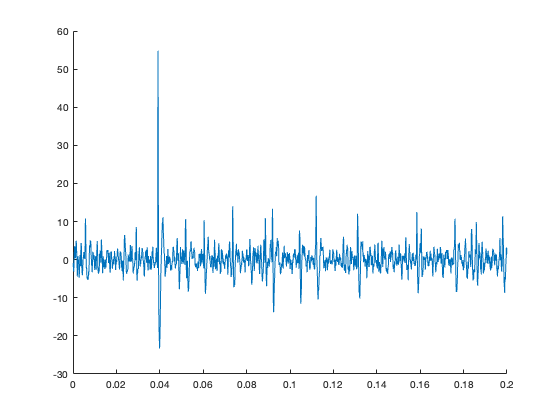

% Chose your threshold with a single click on the filtered data
    figure; hold on; plot(tim(tim < 0.5), vmfilt(tim < 0.5));
    [~, thresh] = ginput(1);

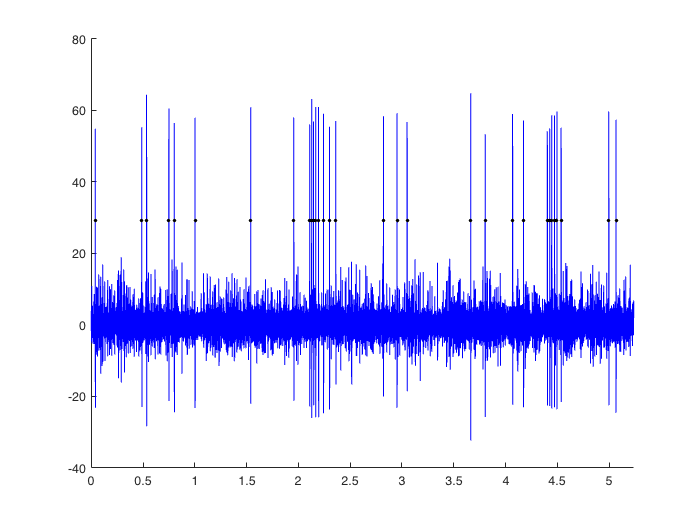

    close(gcf);

% create an empty vector of the length of the data
    Z = zeros(1, length(vmfilt));
% Make every point where the data is above threshold equal to 1 and leave
% everything else as zero
    Z(vmfilt > thresh) = 1;

% Positive zero crossings will have a diff equal to 1   
    indices = find(diff(Z) == 1);

% Convert to seconds
    spiketimes = indices * vm_dt;
    meanSpikeRate = mean(diff(spiketimes));

% and plot
figure; hold on;
    plot(tim, vmfilt, 'b');

    dts = thresh * ones(1,length(spiketimes));
    plot(spiketimes, dts, 'k.', 'MarkerSize', 8);
    xlim([0 meanSpikeRate*30]);

We will need to calculate spikes times for each sample and AM, so we have used the above code to create the function *thresholding.m *that filters the signal, identifies a threshold value, and calculates the spiketimes based on that threshold.

## Characterize baseline activity

Now that you have the spike times (either from the above code or from spike2), you can characterize the baseline activity of these receptors (i.e., the spiking activity without stimulation). To do this we 1) calculate the mean baseline firing rate, 2) determine the interspike interval, 3) compute the coeffiecient of variation, 4) plot the phase distribution relative to the EOD, and 5) measure the degree of phase locking of the spike times releative to the stimulus.

### 1. Baseline activity - no stimulus

% Take data before the first stimulus starts (marker(1))
    spiketimesBaseLine = spiketimes(spiketimes < marker(1)); 

    % Calculate mean baseline firing rate (this varies wildly across neurons)
    meanBaseLinefiringrate = length(spiketimesBaseLine) / max(spiketimesBaseLine);  % Number of spikes divided by time
    fprintf(['Mean baseline firing rate of the neuron is: ' num2str(meanBaseLinefiringrate) ' Hz. \n'])

Mean baseline firing rate of the neuron is: 6.0139 Hz. 



    % Compute the coefficient of variation (CV)
    standard_deviation_isi = std(isi);
    mean_isi = mean(isi);

% Definition of CV
    CV = standard_deviation_isi / mean_isi;
    disp(['CV: ' num2str(CV)])
   

### **2. Plot baseline interspike interval distribution (ISI Histogram) **

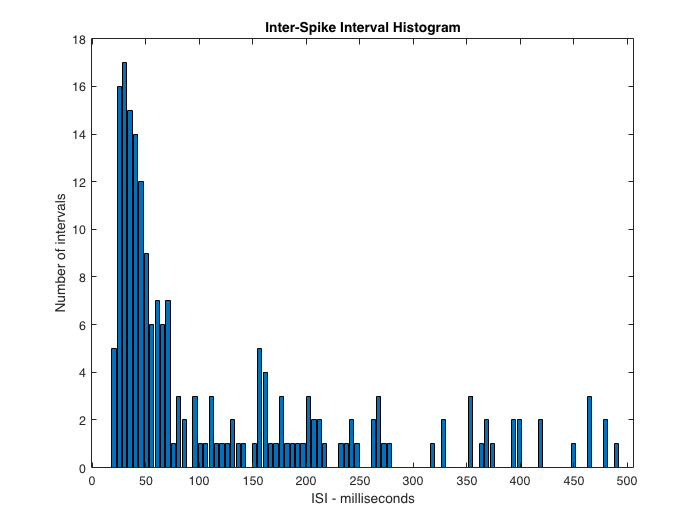

% Compute the ISI sequence - just use diff!
    isi = diff(spiketimesBaseLine); % ISI - times between spikes

% Make a histogram of ISIs - we need bins over the range of ISI durations
    ISIrange = [0.000, 0.010]; % CHOOSE WISELY! This will vary between neurons. (in seconds)

    % Create 100 bins evenly distributed between the min and max of isi
    numbins = 100; % This is the number of bins (default 100)
    ISIbins = linspace(ISIrange(1), ISIrange(2), numbins); 
    % Make the histogram
    numbercounts = histcounts(isi, ISIbins); % Calculate the histogram

% plot ISI histogram
    figure; box on; 
    bar(ISIbins(2:end)*1000, numbercounts);
    xlabel('ISI - milliseconds');
    ylabel('Number of intervals');
    title('Inter-Spike Interval Histogram');

Notice the multimodal distribution. What could give rise to a multimodal distribution?

### **3. Plot phase of spiking relative to the EOD (baseline)**

You might have noticed that receptor afferents tend to fire near a local maximum of the EOD. What about the PCells in the ELL? We can evaluate the phase relationship between the spike train and the EOD. To do this, you’ll need to convert the spike times into phases with respect to the nearest EOD zero crossing.

 Look at the phase distribution (also called a phase histogram) relative to the EOD.

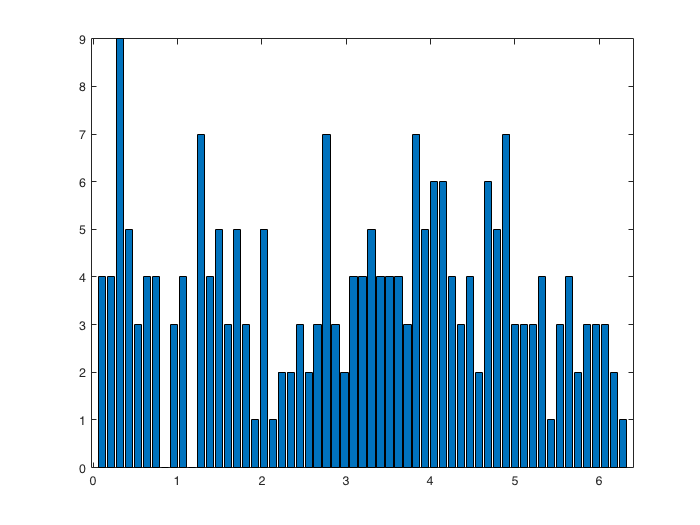

% Compute a phase histogram relative to the EOD. 
% Select the spike times between the 1st and last EOD zero-crossings of our
% sample before the first stimulus occurred - almost all spikes if not all!

spiketimesBaseLine = spiketimesBaseLine(spiketimesBaseLine > EOD0Xings(1)...
    & spiketimesBaseLine < EOD0Xings(end));

% Created an empty vector length of the zerocrossings
      EODSpikephase = zeros(length(spiketimesBaseLine), 1); % PreAllocate for speed

% Loop over the spiketimes
    for I = 1:length(spiketimesBaseLine) % For each spike... 
        ind = find(EOD0Xings <= spiketimesBaseLine(I), 1, 'last'); % Get previous EOD zero Xing
        % Phase is 2pi times the ratio [time from EOD crossing prior to spike] / [duration of the EOD crossing to the subseqent]     
        EODSpikephase(I) = 2 * pi * (spiketimesBaseLine(I) - EOD0Xings(ind)) / (EOD0Xings(ind+1) - EOD0Xings(ind));
    end

% Plot phase distribution
    numbins = 60; % Number of bins for the histogram (60 is default)
    PhaseHistedges = linspace(0, 2*pi, numbins);
    PhaseHistbins = histcounts(EODSpikephase, PhaseHistedges);
    figure; hold on; box on;
    bar(PhaseHistedges(2:end), PhaseHistbins);

### **4. Measure degree of phase locking (vector strength) to EOD**

Vector strenth is used as a measure of phase locking in the audiotry system and ranges between zero and one.

% Compute the vector strength (VS)
    vector_strength = sqrt(mean(cos(EODSpikephase)).^2 + mean(sin(EODSpikephase)).^2);
    disp(['VS: ' num2str(vector_strength)])

VS: 0.073296


# Functions

#### load_data

function [EODOXings, AM, AM_dt, time_AM, vm, vm_dt, dipole, dip_dt, marker] = load_data()
% select and load file
uiopen('.mat');

% load the EOD zero crossings from channel 2
EODOXings = Ch2.times; 

% get the AM values
AM = Ch3.values;

% time vector for the AM stimulus
time_AM = Ch3.times';

% set the sampling interval
AM_dt = Ch3.interval; 

% get the membrane potential values
vm = Ch5.values;

% set the sampling interval
vm_dt = Ch5.interval;

% get the dipole channel values
dipole = Ch6.interval;

% set the sampling interval of the dipole
dip_dt = Ch6.interval;

% get the start points of stimuli
marker = Ch31.times;

clear Ch*
end

#### thresholding

function spiketimes = thresholding(EArec, EAdt)

% % filter
% % create a Butterworth filter with 200 Hz cutoff
% [B, A] = butter(2, 200/(1/2/EAdt), 'high');
% % filter the membrane potential
% recfilt = filtfilt(B, A, EArec);

%% find threshold
%chose your threshold value based on the filtered data
figure; plot(EArec(1:2000)); %changed from recfilt for already filtered data
[~, thresh] = ginput(1);
close(gcf);

% create an empty vector of the length of the data
Z = zeros(1, length(EArec));

%Make every point where the data is above threshold equal to 1 and leave
%everything else as zero
Z(EArec > thresh) = 1;

%diff = X(2) - X(1)
%positive zero crossings will have a diff equal to 1 
indices = find(diff(Z) == 1);

% convert to sec
spiketimes = indices * EAdt;
end

#### phase_histogram

function phase_histogram(Spiketimes, Intervals)

% compute a phase histogram

Spiketimes = Spiketimes(Spiketimes > Intervals(1) & Spiketimes < Intervals(end));

% Created an empty vector 
      Spikephase = zeros(length(Spiketimes), 1); % PreAllocate for speed

% loop over the spiketimes
    for I = 1:length(Spiketimes) % For each spike... 
        ind = find(Intervals <= Spiketimes(I), 1, 'last'); % Get previous EOD zero Xing
        % Phase is 2pi times the ratio [time from EOD crossing prior to spike] / [duration of the EOD crossing to the subseqent]     
        Spikephase(I) = 2 * pi * (Spiketimes(I) - Intervals(ind)) / (Intervals(ind+1) - Intervals(ind));
    end

%plot phase distribution
    PhaseHistedges = linspace(0, 2*pi, 60);
    PhaseHistbins = histcounts(Spikephase, PhaseHistedges);
    figure; hold on; box on;
    bar(PhaseHistedges(2:end), PhaseHistbins);
    
 % compute the vector strength (VS)
    vector_strength = sqrt(mean(cos(Spikephase)).^2 + mean(sin(Spikephase)).^2);
    disp(['VS: ' num2str(vector_strength)])
end